# Code Generation for Incremental Learning

This example shows how to generate code that implements incremental learning for binary linear classification. To motivate its purpose, consider training a wearable device tasked to determine whether the wearer is idle or moving,  based on sensory features the device reads.

The generated code performs the following tasks, as defined in entry-point functions:

- Load a configured incremental learning model template created at the command line.

- Track performance metrics on the incoming batch of data from a data stream. This example tracks misclassification rate and hinge loss.

- Update the model by fitting the incremental model to the batch of data.

- Predicts labels for the batch of data.

This example generates code from the MATLAB® command line, but you can generate code using the MATLAB® Coder™ app instead. For more details, see [Code Generation for Prediction Using MATLAB Coder App](docid:stats_ug.mw_623f82ca-b332-43f8-931e-6771943c8cb3).

All incremental learning object functions for binary linear classification (and also linear regression) support code generation. To prepare code to generate for incremental learning, the object functions require an appropriately configured incremental learning model object, but the `-args` option of [`codegen`](docid:coder_ref.br46oyi-1) does not accept these objects. To work around this limitation, use the [`saveLearnerForCoder`](docid:stats_ug.bvclu99) and [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1) functions.

This flow chart shows the code generation workflows for the incremental learning object functions for linear models.

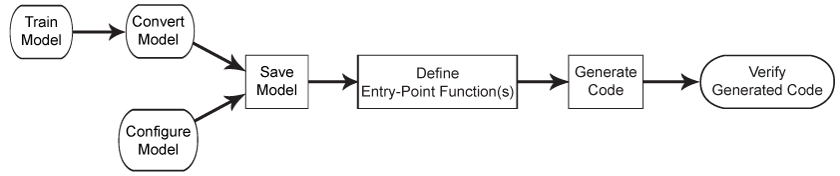

The flow chart suggests two distinct but merging workflows.

- The workflow beginning with **Train Model > Convert Model** requires data, in which case you can optionally perform feature selection or optimize the model by performing cross-validation before generating code for incremental learning. 

- The workflow beginning with **Configure Model** does not require data. Instead, you must manually configure an incremental learning model object.

For details on the differences between the workflows, and for help deciding which one to use, see [docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23](docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23).

Regardless of the workflow you choose, the resulting incremental learning model must have all the following qualities:

- The `NumPredictors` property reflect the number of predictors in the predictor data during incremental learning.

- For classification, the `ClassNames` property must contain all class names expected during incremental learning.

If you choose the **Train Model > Convert Model** workflow and you fit the model to data containing all known classes, the model is configured for code generation. 

After you prepare an incremental learning model, save the model object by using `saveLearnerForCoder`. Then, define an entry-point function that loads the saved model by using `loadLearnerForCoder`, and that performs incremental learning by calling the object functions. Alternatively, you can define multiple entry-point functions that perform the stages of incremental learning separately (this example uses this workflow). However, this workflow requires special treatment when an updated model object is an input to another entry-point function. For example, you write the following three entry-point functions: 

- A function that accepts the current model and a batch of data, calls [`updateMetrics`](docid:stats_ug#mw_c5db68b3-16a1-4b8b-90b9-7f3c76289dce), and returns a model with updated performance metrics.

- A function that accepts the updated model and the batch of data, calls [`fit`](docid:stats_ug#mw_665feb66-5ad1-4a02-8d42-32a1a738997c), and returns a model with updated coefficients. 

- A function that accepts the further updated model and the batch of predictor data, calls [`predict`](docid:stats_ug#mw_1d13a443-0b4a-44bb-a4df-c34b8a9ce1d5), and returns predicted labels.

Finally, generate code for the entry-point functions by using `codegen`, and verify the generated code. 

## Load and Preprocess Data

Load the human activity data set. Randomly shuffle the data.

idxTestAll;
idxTestAll_batIndex;
idxTestAll_batIndex1 = (idxTestAll_batIndex == 16);
idxTest;
idxAll;

find(idxTestAll_batIndex == idxTest(7));
idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)));

RUL(idxTestAll_test1);
test_bat = idxTest(7);
RUL_test = RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)));
ynorm_RUL_test = ynorm_RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)));
SOH_test = Cap(idxTestAll(find(idxTestAll_batIndex == test_bat)));
ynorm_SOH_test = ynorm_SOH(idxTestAll(find(idxTestAll_batIndex == test_bat)));

Ic_test = Ic(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
Vd_test = Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
xnorm_Vd_test = xnorm_Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
ytrain = ynorm_RUL_test;
Xtrain = xnorm_Vd_test;


idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)));
idxFindAll = find(idxTestAll_batIndex == idxFind);
Y_test_RUL_test1 = Y_test_RUL(idxFindAll);
Y_test_SOH_test1 = Y_test_SOH(idxFindAll);


compareTo = Y_test_RUL_test1(1);

idx = idxTestSort(idxSearch); %16
% find most similar data
idxTrainValid = [idxTrain idxValid];

count = length(idxTrain) + length(idxValid);
idxSel = 0;
diff = 1000;
for i=1:count 
    diff_new = abs( ryan4_battery_dataset(idxTrainValid(i)).cycle_life - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
    end
end

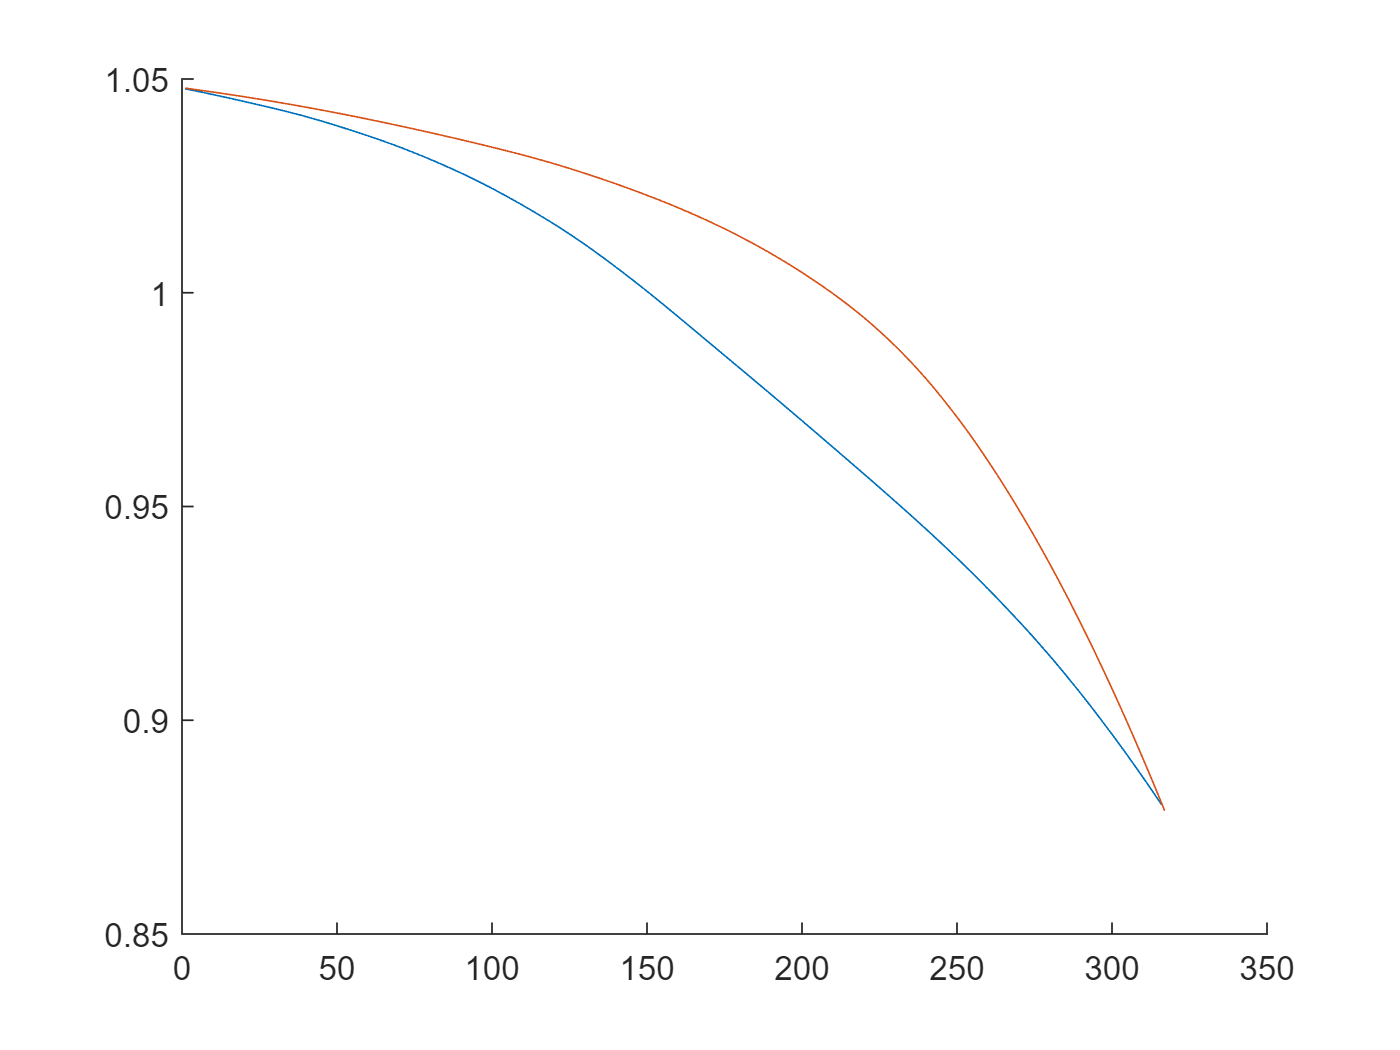


matchedRUL = ryan4_battery_dataset(idxSel).cycle_life;
inTrain = any(idxTrain==idxSel);

if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1;

figure, hold on
plot(ryan4_battery_dataset(idx).QDischargeSmooth)
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth)
hold off



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)));
idxFindAll2 = find(idxTestAll_batIndex == idxFind2);
Y_test_RUL_test2 = Y_test_RUL(idxFindAll2);
% Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2);


load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

`Metrics` **—** **Model performance metrics to track during incremental learning**

`"classiferror"` (default) | function handle | cell vector | structure array

Model performance metrics to track during incremental learning with the [`updateMetrics`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.updatemetrics.html) or [`updateMetricsAndFit`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.updatemetricsandfit.html) function, specified as `"classiferror"` ([classification error](https://www.mathworks.com/help/releases/R2022a/stats/classificationecoc.incrementallearner.html#mw_8fb753e8-05af-4a54-87db-7942764683c7_sep_shared-ClassificationError), or misclassification error rate), a function handle (for example, `@metricName`), a structure array of function handles, or a cell vector of names, function handles, or structure arrays.

To specify a custom function that returns a performance metric, use function handle notation. The function must have this form.

`metric = customMetric(C,S)`

- The output argument `metric` is an *n*-by-1 numeric vector, where each element is the loss of the corresponding observation in the data processed by the incremental learning functions during a learning cycle.

- You specify the function name (here, `customMetric`).

- `C` is an *n*-by-*K* logical matrix with rows indicating the class to which the corresponding observation belongs, where *K* is the number of classes. The column order corresponds to the class order in the `ClassNames` property. Create `C` by setting `C(``p``,``q``)` = `1`, if observation `p` is in class `q`, for each observation in the specified data. Set the other element in row `p` to `0`.

- `S` is an *n*-by-*K* numeric matrix of predicted classification scores. `S` is similar to the `NegLoss` output of [`predict`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.predict.html), where rows correspond to observations in the data and the column order corresponds to the class order in the `ClassNames` property. `S(``p``,``q``)` is the classification score of observation `p` being classified in class `q`.

To specify multiple custom metrics and assign a custom name to each, use a structure array. To specify a combination of built-in and custom metrics, use a cell vector.

`updateMetrics` and `updateMetricsAndFit` store specified metrics in a table in the [`Metrics`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.html#mw_d0011a91-b04d-4865-b03c-435eaf011563_sep_shared-incrementallearner_metrics_prop) property. The data type of `Metrics` determines the row names of the table.

`Metrics` **Value Data Type****Description of** `Metrics` **Property Row Name****Example**

String or character vectorName of corresponding built-in metricRow name for `"classiferror"` is `"ClassificationError"`

Structure arrayField nameRow name for `struct(Metric1=@customMetric1)` is `"Metric1"`

Function handle to function stored in a program fileName of functionRow name for `@customMetric` is `"customMetric"`

Anonymous function`CustomMetric_``j`, where `j` is metric `j` in `Metrics`Row name for `@(C,S)customMetric(C,S)...` is `CustomMetric_1`

For more details on performance metrics options, see [Performance Metrics](https://www.mathworks.com/help/releases/R2022a/stats/classificationecoc.incrementallearner.html#mw_8fb753e8-05af-4a54-87db-7942764683c7_sep_shared-incrementallearner_metrics_algo_head).

**Example:** `Metrics=struct(Metric1=@customMetric1,Metric2=@customMetric2)`

**Example:** `Metrics={@customMetric1,@customMetric2,"classiferror",struct(Metric3=@customMetric3)}`

**Data Types:** `char` | `string` | `struct` | `cell` | `function_handle`

[https://kr.mathworks.com/matlabcentral/answers/629998-how-to-save-loss-rmse-mae-and-mape-in-every-training-epoch](https://kr.mathworks.com/matlabcentral/answers/629998-how-to-save-loss-rmse-mae-and-mape-in-every-training-epoch)

Is there any suggestion on how to save the loss, rmse, mae, and mape in every training epoch? I want to compare them in condition of different parameters later.

Cheers

FYI I calculate the rmse, mae, and mape in the end like this:

ThemeCopy

`net = trainNetwork(XTrain,YTrain,layers,options);`

`net = predictAndUpdateState(net,XTrain);`

`[net,YPred] = predictAndUpdateState(net,XTest);`

`YPred = sig(1)*YPred + mu(1);`

`YTest = dataTest(1,:);`

`rmse = sqrt(mean((YPred-YTest).^2))`

`mae = mean(abs(YPred-YTest))`

`mape = mean(abs((YPred-YTest)./YTest))*100`

rmsefcn = @(z,zfit)sqrt(mean((z - zfit).^2));
msefcn = @(z,zfit)mean((z - zfit).^2);
maefcn = @(z,zfit)abs(z - zfit);
mapefcn = @(z,zfit)mean(abs(z - zfit)/z)*100;

Metrics={'mse'}

Metrics = 1×1 cell array
    {'mse'}


%Metrics={'mse',struct(MeanAbsoluteError=@myMAE),struct(RootMeanSquareError=@myRMSE),struct(MeanAbsolutePercentageError=@myMAPE)}
% Metrics={"mse",struct(RootMeanSquarError=@rmsefcn),struct(MeanAbsoluteError=@maefcn),struct(MeanAbsolutePercentiageError=@mapefcn)}

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

`Metrics={"mse",struct(MeanAbsoluteError=@maefcn)}`

`??? Undefined function or variable 'maefcn'.`

`Error in ==> `[`incrementalRegressionLinear Line: 187 Column: 43`](matlab: emlcprivate('emcopentoline','C:\Program Files\MATLAB\R2022a\toolbox\stats\incremental\+incremental\+coder\incrementalRegressionLinear.m',187,43);)

`Code generation failed: `[`View Error Report`](matlab: open('C:\nobackup\_phd_work\_battery_soh\_matlab_battery\_mywork\_latest\codegen\mex\myIncrLearn_mex\html\report.mldatx');)



n = numel(ytrain);
IncrementalMdl = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',Metrics ...
    )

IncrementalMdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


    % 'Metrics',{ 'mse'  maemetric }...

mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


## Configure Incremental Learning Model

To generate code for incremental classification, you must appropriately configure a binary classification linear model for incremental learning `incrementalClassificationLinear`. 

Create a binary classification (SVM) model for incremental learning.  Fully configure the model for code generation by specify all expected class names and the number of predictor variables. Also, specify tracking the misclassification rate and hinge loss. For reproducibility, this example turns off observation shuffling for the scale-invariant solver.

% metrics = ["classiferror" "hinge"];
% IncrementalMdl = incrementalClassificationLinear('ClassNames',classnames,'NumPredictors',p,...
%     'Shuffle',false,'Metrics',metrics)

`Mdl` is an `incremenalClassificationLinear` model object configured for code generation. `Mdl` is *cold* (`Mdl.IsWarm` is `0`) because it has not processed data—the coefficients are `0`.

Alternatively, because the data is available, you can fit an SVM model to the data by using either `fitcsvm` or `fitclinear`, and then convert the resulting model to an incremental learning model by passing the model to `incrementalLearner`. The resulting model is *warm* because it has processed data—its coefficients are likely non-zero.

## Save Model Using `saveLearnerForCoder`

Save the incremental learning model to the file `InitialMdl.mat` by using [`saveLearnerForCoder`](docid:stats_ug.bvclu99). 

% saveLearnerForCoder(IncrementalMdl,'InitialMdl');
saveLearnerForCoder(IncrementalMdl,'InitialMdl');

`saveLearnerForCoder` saves the incremental learning model to the MATLAB binary file `SVMClassIncrLearner.mat` as structure arrays in the current folder.

## Define Entry-Point Functions

An *entry-point* function, also known as the *top-level* or *primary* function, is a function you define for code generation. Because you cannot call any function at the top level using `codegen`, you must define an entry-point function that calls code-generation-enabled functions, and generate C/C++ code for the entry-point function by using `codegen`. All functions within the entry-point function must support code generation.

Define four separate entry-point functions in your current folder that perform the following actions:

- `myInitialModelIncrLearn.m` — Load the saved model by using [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1), and return a model of the same form for code generation. This entry-point function facilitates the use of a model, returned by an entry-point function, as an input to another entry-point function.

- `myUpdateMetricsIncrLearn.m` — Measure the performance of the current model on an incoming batch of data, and store the performance metrics in the model. The function accepts the current model, and predictor and response data, and returns an updated model.

- `myFitIncrLearn.m` — Fit the current model to the incoming batch of data, and store the updated coefficients in the model. The function accepts the current model, and predictor and response data, and returns an updated model. 

- `myPredictIncrLearn.m` — Predicted labels for the incoming batch of data using the current model. The function accepts the current model and predictor data, and returns labels and class scores.

For more details on generating code for multiple entry-point functions, see [docid:coder_ug#bsd8i4b-1](docid:coder_ug#bsd8i4b-1).

Add the `%#codegen` compiler directive (or pragma) to the entry-point function after the function signature to indicate that you intend to generate code for the MATLAB algorithm. Adding this directive instructs the MATLAB Code Analyzer to help you diagnose and fix violations that would result in errors during code generation. See [Check Code with the Code Analyzer](docid:coder_ug.btln3cg).

Alternatively, you can access the functions in `mlr/examples/stats/main`, where `mlr` is the value of `matlabroot`.

Display the body of each function.

type myInitialModelIncrLearn.m
type myUpdateMetricsIncrLearn.m
type myUpdateMetricsAndFitIncrLearn.m
type myFitIncrLearn.m
type myPredictIncrLearn.m

## Generate Code

**Set Up Compiler**

To generate C/C++ code, you must have access to a C/C++ compiler that is configured properly. MATLAB Coder locates and uses a supported, installed compiler. You can use `mex` `-setup` to view and change the default compiler. For more details, see [Change Default Compiler](docid:matlab_external.btw3qmj).

**Build Type**

MATLAB Coder can generate code for the following build types: 

- MEX (MATLAB Executable) function

- Standalone C/C++ code

- Standalone C/C++ code compiled to a static library

- Standalone C/C++ code compiled to a dynamically linked library

- Standalone C/C++ code compiled to an executable

You can specify the build type using the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1). For more details on setting code generation options, see the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1) and [Configure Build Settings](docid:coder_ug.bsw7_wl).

By default, `codegen` generates a MEX function. A MEX function is a C/C++ program that is executable from MATLAB. You can use a MEX function to accelerate MATLAB algorithms and to test the generated code for functionality and run-time issues. For details, see [MATLAB Algorithm Acceleration](docid:coder_doccenter#bs2r9v8-1) and [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

**Generate Code Using **`codegen`

Because C and C++ are statically typed languages, you must specify the properties of all variables in the entry-point function at compile time. Specify the following:

- The data types of the data inputs of the entry-point functions by using [`coder.typeof`](docid:coder_ref.bsu_35x). Also, because the number of observations can vary from batch to batch, specify that the number of observations (first dimension) has variable size. For details, see [Specify Variable Sized Arguments for Code Generation](docid:stats_ug.bvnu22q) and [Specify Properties of Entry-Point Function Inputs](docid:coder_ug.bq9_nbz).

- Because several entry-point functions accept an incremental model object as a input, and operate on it, create a representation of the model object for code generation by using [`coder.OutputType`](docid:coder_ref#mw_186147ed-8160-4651-9402-66b666c36a83). For more details, see [docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538](docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538).

% predictorData = coder.typeof(X,[],[true false]); 
% responseData = coder.typeof(Y,[],true);
% IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% predictorData = coder.typeof(ones(5,20)); %coder.typeof(Xtrain); 
% responseData = coder.typeof(ones(5));  ^coder.typeof(ytrain);


function incrementalModel = myInitialModelIncrLearn() %#codegen
% MYINITIALMODELINCRLEARN Load and return configured linear model for
% binary classification InitialMdl
    incrementalModel = loadLearnerForCoder('InitialMdl');
end


predictorData = coder.typeof(Xtrain(1:5,:)); 

function incrementalModel = myUpdateMetricsIncrLearn(incrementalModel,X,Y) %#codegen
% MYUPDATEMETRICSINCRLEARN Measure model performance metrics on new data
      incrementalModel = updateMetrics(incrementalModel,X,Y); 
end


responseData = coder.typeof(ytrain(1:5));

function incrementalModel = myUpdateMetricsAndFitIncrLearn(incrementalModel,X,Y) %#codegen
% MYUPDATEMETRICSINCRLEARN Measure model performance metrics on new data
      incrementalModel = updateMetricsAndFit(incrementalModel,X,Y); 
end


observedData = coder.typeof(ytrain(1:5));

function incrementalModel = myFitIncrLearn(incrementalModel,X,Y) %#codegen
% MYFITINCRLEARN Fit model to new data
      incrementalModel = fit(incrementalModel,X,Y); 
end


function [labels] = myPredictIncrLearn(incrementalModel,X) %#codegen
% MYPREDICTINCRLEARN Predict labels and classification scores on new data
      [labels] = predict(incrementalModel,X); 
end



IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');


Generate code for the entry-point functions using [`codegen`](docid:coder_ref.br46oyi-1).  For each entry-point function argument, use the `-args` flags to specify the coder representations of the variables. Specify the output MEX function name `myIncrLearn_mex`. 

 codegen -o myIncrLearn_mex ...
 myInitialModelIncrLearn ... 
 myMAE –args {observedData,responseData} ...
 myRMSE –args {observedData,responseData} ...
 myMAPE –args {observedData,responseData} ...
 myMSE –args {observedData,responseData} ...
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} -report

For help debugging code generation issues, view the generated C/C++ code by clicking `View report` (see [Code Generation Reports](docid:coder_ug.brbmkp4-1)).

## Verify Generated Code

Test the MEX function to verify that the generated code provides the same functionality as the original MATLAB code. To perform this test, run the MEX function using the same inputs that you used to run the original MATLAB code, and then compare the results. Running the MEX function in MATLAB before generating standalone code also enables you to detect and fix run-time errors that are much harder to diagnose in the generated standalone code. For more details, see [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

Perform incremental learning by using the generated MEX functions and directly by using the object functions. Specify a batch 

% % Preallocation
% numObsPerChunk = 50;
% nchunk = floor(n/numObsPerChunk);
% ce = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% hinge = ce;
% ceCG = ce;
% hingeCG = ce;
% IncrementalMdlCG = myIncrLearn_mex('myInitialModelIncrLearn');
% scores = zeros(n,2);
% scoresCG = zeros(n,2);

Code generation successful: View report



% 
% % Incremental fitting
% for j = 1:nchunk
%     ibegin = min(n,numObsPerChunk*(j-1) + 1);
%     iend   = min(n,numObsPerChunk*j);
%     idx = ibegin:iend;
% 
%     IncrementalMdl = updateMetrics(IncrementalMdl,X(idx,:),Y(idx));
%     ce{j,:} = IncrementalMdl.Metrics{"ClassificationError",:};
%     hinge{j,:} = IncrementalMdl.Metrics{"HingeLoss",:};
%     IncrementalMdlCG = myIncrLearn_mex('myUpdateMetricsIncrLearn',IncrementalMdlCG,...
%         X(idx,:),Y(idx));
%     ceCG{j,:} = IncrementalMdlCG.Metrics{"ClassificationError",:};
%     hingeCG{j,:} = IncrementalMdlCG.Metrics{"HingeLoss",:};
% 
%     IncrementalMdl = fit(IncrementalMdl,X(idx,:),Y(idx));
%     IncrementalMdlCG = myIncrLearn_mex('myFitIncrLearn',IncrementalMdlCG,X(idx,:),Y(idx));
%     
%     [~,scores(idx,:)] = predict(IncrementalMdl,X(idx,:));
%     [~,scoresCG(idx,:)] = myIncrLearn_mex('myPredictIncrLearn',IncrementalMdlCG,X(idx,:));
% end


n = numel(ytrain);

% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);

IncrementalMdlCG = myIncrLearn_mex('myInitialModelIncrLearn');

ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

ei_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10_CG = zeros(nchunk,1);    


y_predict = []; %zeros();
y_predict_CG = [];

% Incremental fitting
rng("default"); % For reproducibility
IncrementalMdl.Beta' ;
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   ;
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    IncrementalMdl = updateMetricsAndFit(...
        IncrementalMdl,...
        Xtrain(idx,:),...
        ytrain(idx));

    IncrementalMdlCG = myIncrLearn_mex('myUpdateMetricsAndFitIncrLearn', ... 
        IncrementalMdlCG,...
        Xtrain(idx,:),...
        ytrain(idx));

    y_predict_temp = predict(IncrementalMdl,Xtrain(idx,:));

    y_predict_temp_CG = myIncrLearn_mex('myPredictIncrLearn',IncrementalMdlCG,Xtrain(idx,:)); 

    IncrementalMdl.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    y_predict_CG = [ y_predict_CG ; y_predict_temp_CG ];

    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp];
    [ytrain(idx) y_predict_temp_CG ytrain(idx)-y_predict_temp_CG];

    %ei{j,:} = IncrementalMdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = IncrementalMdl.Metrics{"MeanSquaredError",:};
    beta10(j + 1) = IncrementalMdl.Beta(10);
    %mae{j,:} = IncrementalMdl.Metrics{"MeanAbsoluteError",:};

    mse_val_CG{j,:} = IncrementalMdlCG.Metrics{"MeanSquaredError",:};
    beta10_CG(j + 1) = IncrementalMdlCG.Beta(10);
    %mae_CG{j,:} = IncrementalMdlCG.Metrics{"MeanAbsoluteError",:};

    IncrementalMdlCG.Metrics
    [ IncrementalMdlCG.Metrics{"MeanSquaredError",:} IncrementalMdlCG.Beta(10)]
    
%     ceCG{j,:} = IncrementalMdlCG.Metrics{"ClassificationError",:};
%     hingeCG{j,:} = IncrementalMdlCG.Metrics{"HingeLoss",:};
end

ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2338


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2354


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2352


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2359


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2334


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2332


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2365


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00026787     NaN  


ans =     0.0003       NaN    0.2354


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00044501     NaN  


ans =     0.0004       NaN    0.2371


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00038014     NaN  


ans =     0.0004       NaN    0.2383


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.0002999      NaN  


ans =     0.0003       NaN    0.2389


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00024481    0.00024481


ans =     0.0002    0.0002    0.2392


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00020768    0.00024481


ans =     0.0002    0.0002    0.2395


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00018269    0.00024481


ans =     0.0002    0.0002    0.2398


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00016778    0.00024481


ans =     0.0002    0.0002    0.2404


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00017608    0.00024481


ans =     0.0002    0.0002    0.2415


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00017297    0.00010112


ans =     0.0002    0.0001    0.2424


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00015803    0.00010112


ans =     0.0002    0.0001    0.2425


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014694    0.00010112


ans =     0.0001    0.0001    0.2429


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014082    0.00010112


ans =     0.0001    0.0001    0.2433


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00015058    0.00010112


ans =     0.0002    0.0001    0.2446


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014092    7.6821e-05


ans =     0.0001    0.0001    0.2447


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00013214    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2447


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError     0.000125     7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2445


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00011849    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2442


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00011271    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2440


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00010747    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2438


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00010273    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2435


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.8289e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2433


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.4333e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2431


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.0495e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2430


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.7693e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2426


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.4353e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2426


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.1544e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2424


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0614e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2418


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.803e-05     8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2416


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.6489e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2413


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0074e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2402


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.8601e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2404


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.2311e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2415


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0421e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.8135e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2418


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.6227e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2416


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.6729e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2408


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.5159e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2409


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.7666e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2419


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.614e-05     6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2421


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.4298e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2422


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.2567e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2422


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.1789e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2418


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.0874e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2414


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.0346e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.905e-05     2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2420


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.7724e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.6451e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2416


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.5439e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2413


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.5531e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2407


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.4542e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2404


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.3471e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2406


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.2366e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2404


Compare the cumulative metrics and scores for classifying `Idle` returned by the object functions and MEX functions.

% idx = all(~isnan(ce.Variables),2);
% areCEsEqual = norm(ce.Cumulative(idx) - ceCG.Cumulative(idx))
% idx = all(~isnan(hinge.Variables),2);
% areHingeLossesEqual = norm(hinge.Cumulative(idx) - hingeCG.Cumulative(idx))
% areScoresEqual = norm(scores(:,1) - scoresCG(:,1))

IncrementalMdlCG.Metrics

ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.2366e-05    2.2191e-05


idx = find(~isnan(mse_val_CG.Cumulative))

idx = 53×1
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20


idxWin = find(~isnan(mse_val.Cumulative))

idxWin = 53×1
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20



%idxWin = linspace(1,size(mse_val_CG,1),size(mse_val,1))
mse_val.Cumulative(idx) - mse_val_CG.Cumulative(idx)

ans = 53×1
1.0e-17 *

   -0.7156
   -0.5096
   -0.3632
   -0.3469
   -0.3144
   -0.2982
   -0.2494
   -0.2304
   -0.1328
   -0.0976


areMSEsEqualCumulative = norm(mse_val.Cumulative(idx) - mse_val_CG.Cumulative(idx))

areMSEsEqualCumulative = 1.2389e-17

mse_val.Window(idxWin) - mse_val_CG.Window(idxWin)

ans = 53×1
1.0e-17 *

       NaN
       NaN
       NaN
       NaN
   -0.3090
   -0.3090
   -0.3090
   -0.3090
   -0.3090
    0.1233


areMSEsEqualWindow = norm(mse_val.Window(idxWin) - mse_val_CG.Window(idxWin))

areMSEsEqualWindow = NaN


idx = linspace(1,size(beta10,1),size(beta10,1))

idx = 1×64
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


areBeta10sEqual = norm(beta10(idx) - beta10_CG(idx))

areBeta10sEqual = 6.6091e-16

The differences between the returned quantities are negligible.

*Copyright 2021 The MathWorks, Inc.*